### Integrantes : Miguel Gutierrez y Julian Ramirez

# Punto 1

a. Tablero de ajedrez

A1 = ones(16,16);
for i=1:16;
    if mod(i,2)==0;
      for j=2:2:16;
        A1(i,j)=0;
      end
    else
        for j=1:2:16;
            A1(i,j)=0;
        end
    end
end
disp(A1)

     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0

b. Comando

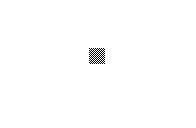

figure(1); 
imshow(A1)

d. 100X100

total=ones(100);
for i=1:7;
    r=zeros(100);
    w=ones(100);
    total=[total,r,w];
end
total=[total,zeros(100)];
for i=2:16  ;
   if mod(i,2)==0;
       x=zeros(100);
        for j=1:7;
            v=ones(100);
            y=zeros(100);
            x=[x,v,y];
        end
        x=[x,ones(100)];
        total=[total;x];
   else
       x=ones(100);
       for j=1:7;
            v=ones(100);
            y=zeros(100);
            x=[x,y,v];
       end
       x=[x,zeros(100)];
       total=[total;x];
   end
end


A2=total;
disp(total)

  Columns 1 through 29

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     

e. Guardando imagen

%imwrite(A2,'ajedrez_miguelgutierrez_julianramirez.bmp')

f. Cargando imagen

A3=imread('ajedrez.bmp')

A3 = 85×119 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1  

g. Cambiando los colores

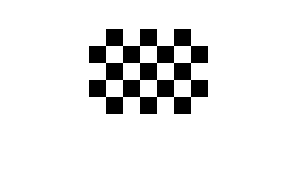

[x, ~, y] = unique(A3); % valores y cantidad de ceros y unos

A3_cambio = [1; 0]; % reorganizo los codigos
A3_nueva = A3_cambio(y);
A3_nueva = reshape(A3_nueva, size(A3));
figure(2)
imshow(A3)

# Punto 2

Vamos primero a cargar la imagen.

B1 = imread('balcones256.bmp'); % Guardando Imagen en la matriz B1
media = mean(B1(:));

Lo modificamos para que nos de una mejor imagen, creamos el algoritmo

B1_binary = B1 > media; %Transforma en 1 si es mayor que la media, y 0 si es menor que la media
B1_binary

B1_binary = 294×720 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

Mostramos la imagen

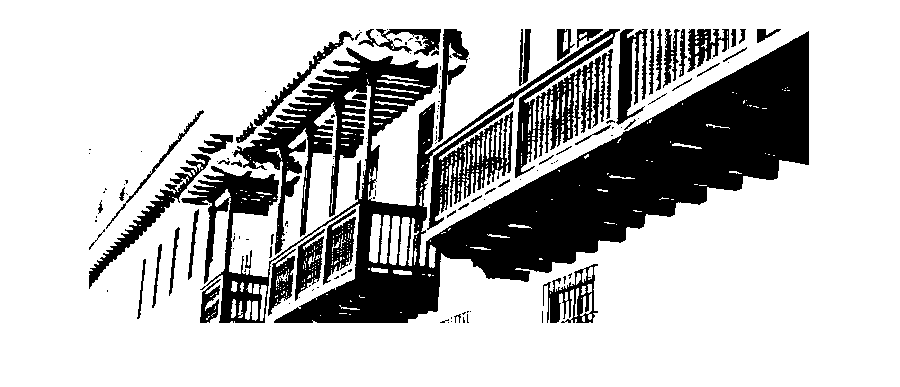

imshow(B1_binary) % muestra imagen

Guardamos la imagen

imwrite(B1_binary,'balconesBN_MiguelGutierrez_JulianRamirez.bmp')

# Punto 3

Definimos primero el tamaño de la imagen

RGB = zeros(600,1000,3); %crea matriz de ceros en 3 dimensiones

Visualizamos la imagen

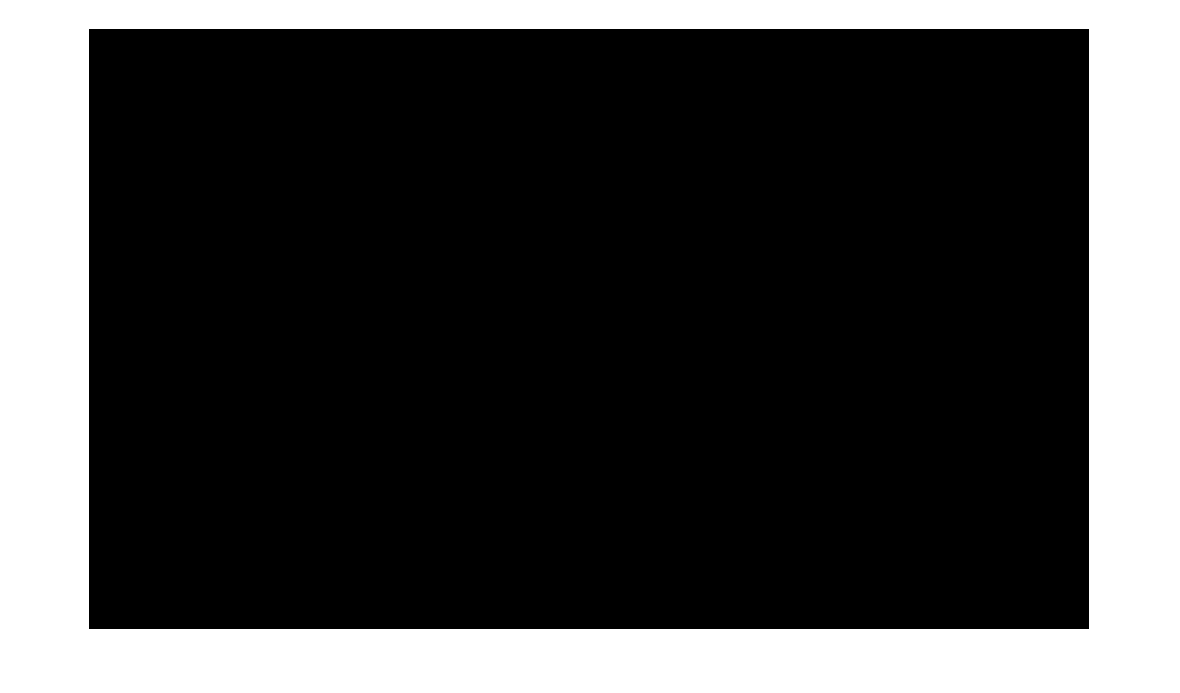

imshow(RGB)

Adicionamos el color rojo en la parte superior central, esto es poner el amximo valor entre las fila 1 y 400, y las columnas 201 a 801. Esto solo para la primera matriz (De rojos)

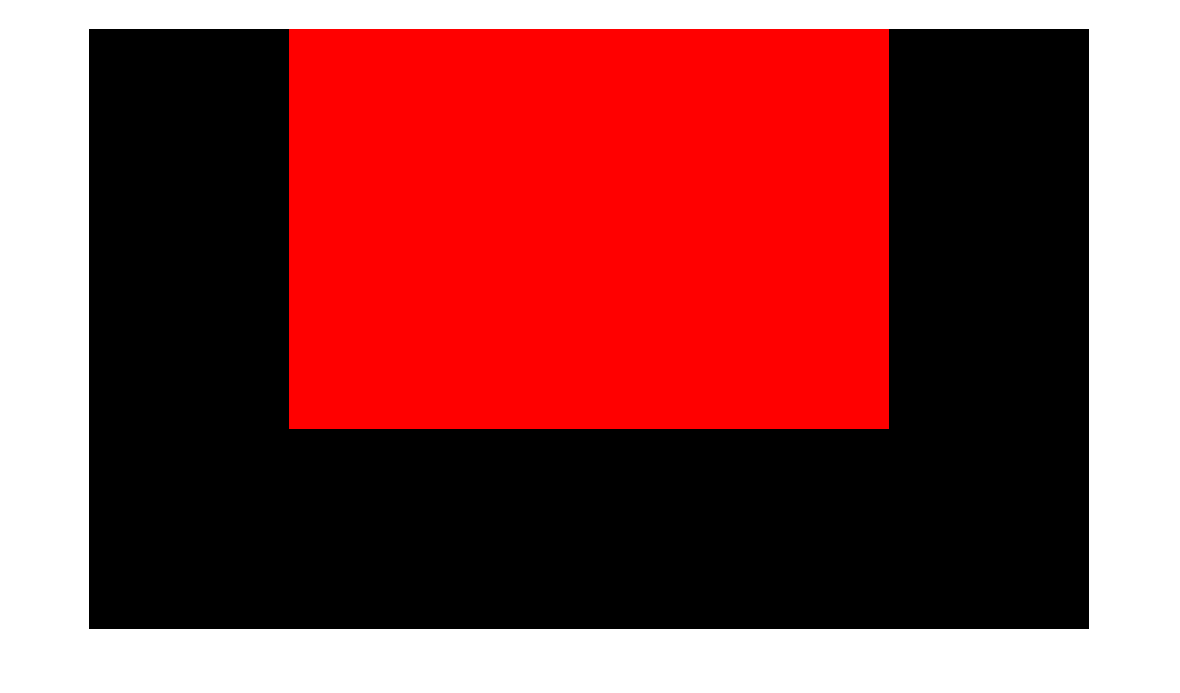

RGB(1:400,201:800,1)=255;
imshow(RGB)

Adicionames el color verde entre las filas 201 a 600 y entre las columnas 1 a 601

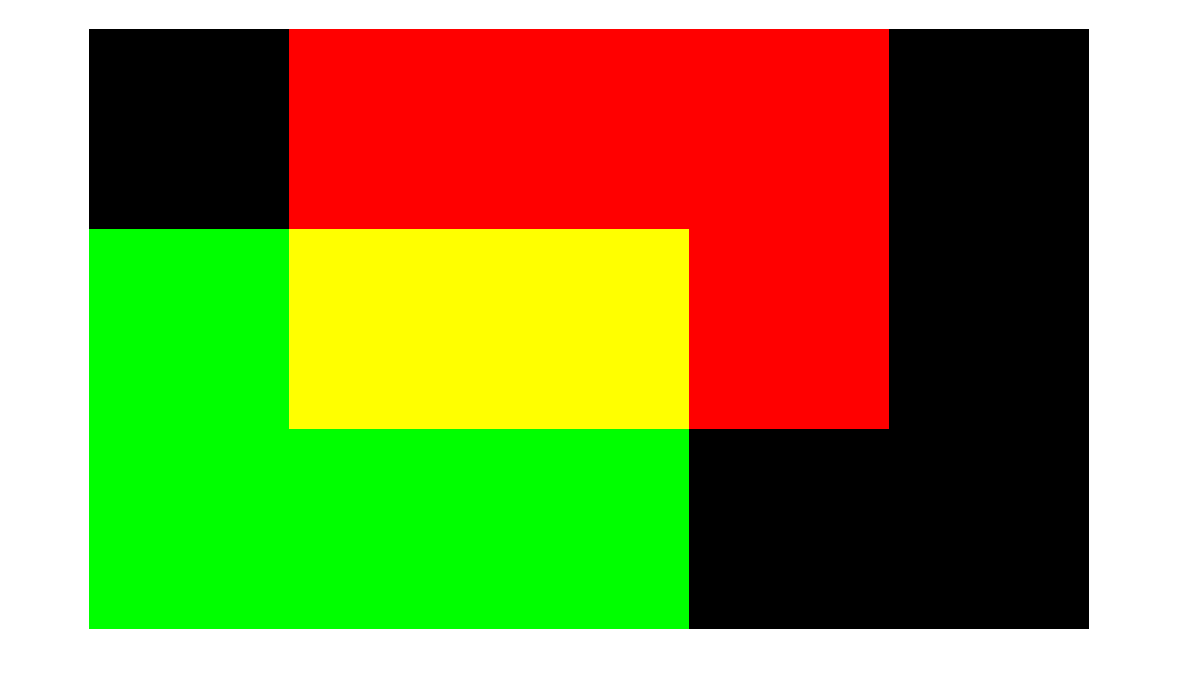

RGB(201:600,1:600,2)=255;
imshow(RGB)

Finalmente agregamos el color azul, en la parte inferior derecha entre las filas 201 a 600 y las columnas 401

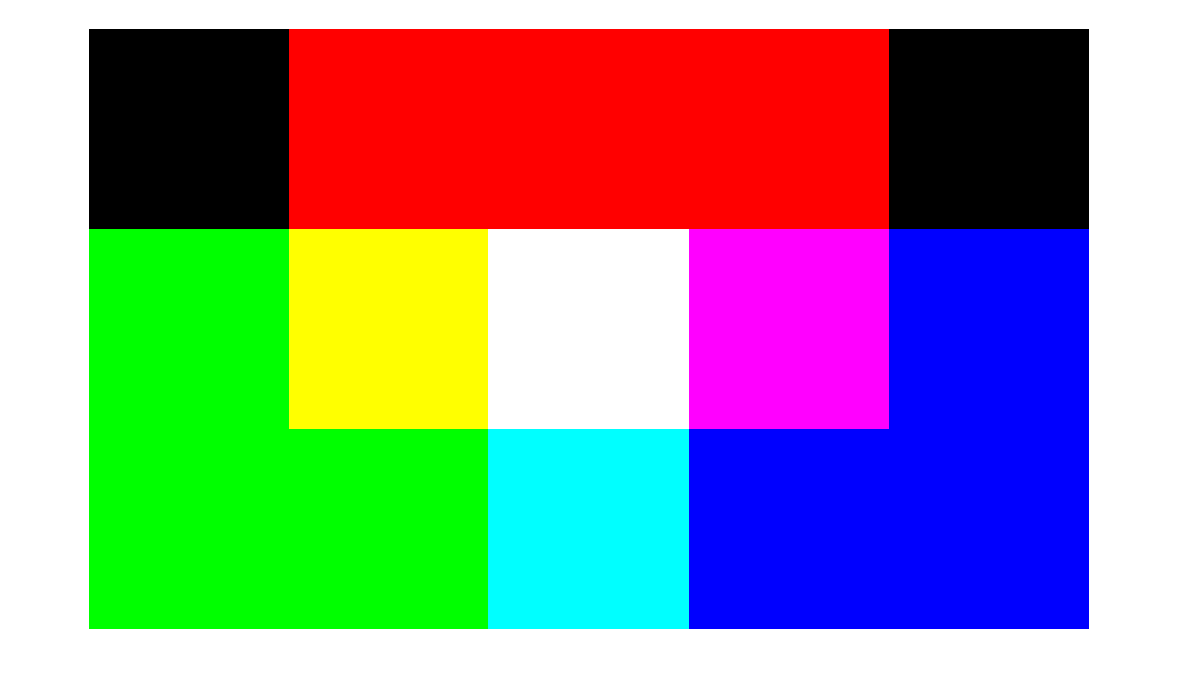

RGB(201:600,400:1000,3)=255;
imshow(RGB)

De esta manera tenemos que:

Rojo : 1 matriz

Verde : 2 Matriz

Azul : 3 Matriz

Ahora agregamos la bandera de colombia, primero creamos la imagen

RGBC = zeros(400,600,3);

Añadimos el azul y rojo abajo

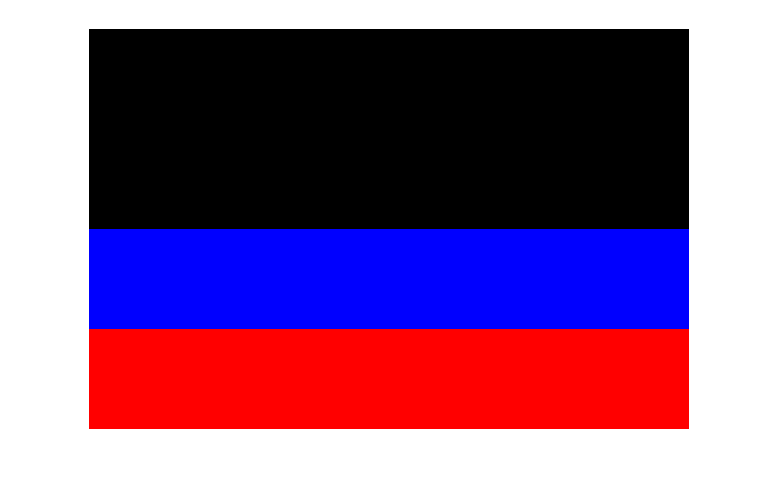

RGBC(301:400,1:600,1)=255;
RGBC(201:300,1:600,3)=255;
imshow(RGBC)

Añadimos el amarillo = Verde + Rojo

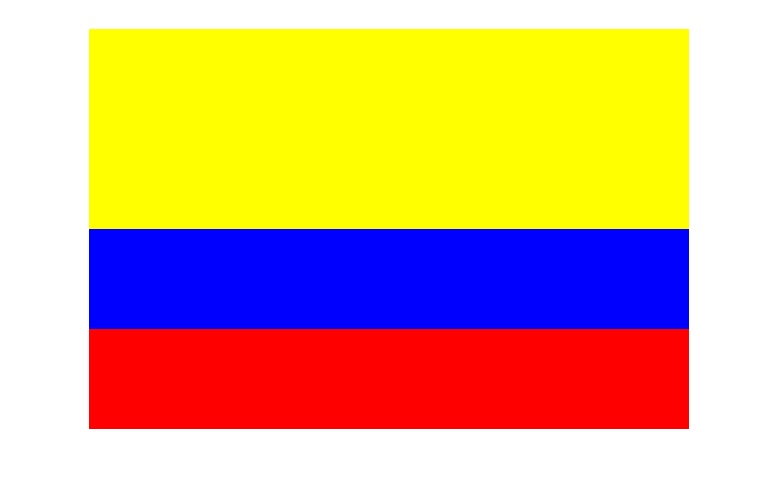

RGBC(1:200,1:600,1)=255;
RGBC(1:200,1:600,2)=255;
imshow(RGBC)

¡ Colombia Grande Querida !

# Punto 4

#### Guacamaya

guaca = imread('guacamaya.jpg')

guaca = 460×700×3 uint8 array
guaca(:,:,1) =

     5     4     5     6     7     8    10     9     4     5     6     8     7     4     6     9    10    12    13    10    11    12    14    12    14    15    18    18    20    20    20    21    21    23    23    24    23    22    23    21    23    22    22    21    20    21    20    21    25    25    26    28    32    34    33    32    31    30    32    35    40    38    37    36    41    37    37    40    42    40    40    40    37    38    38    36    32    29    28    28    21    20    20    21    18    16    13    13    11    10     8     7     7     6     5     4     6     5     8    10    15    20    21    23    29    35    39    44    49    53    57    58    65    69    73    76    77    76    75    74    70    67    66    61    57    53    52    52    50    51    50    48    47    48    47    46    46    46    45    42    41    39    38    37    33    33    31    29    27    26    24    21    24    22    19    18    18    16    12

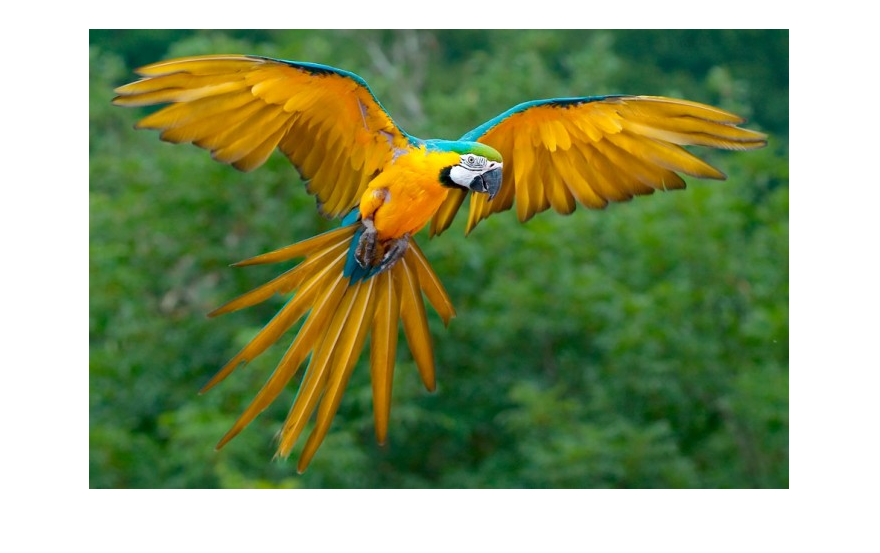

imshow(guaca)

Eliminamos la componente verde,sabemos que la matriz es de 460 x 700

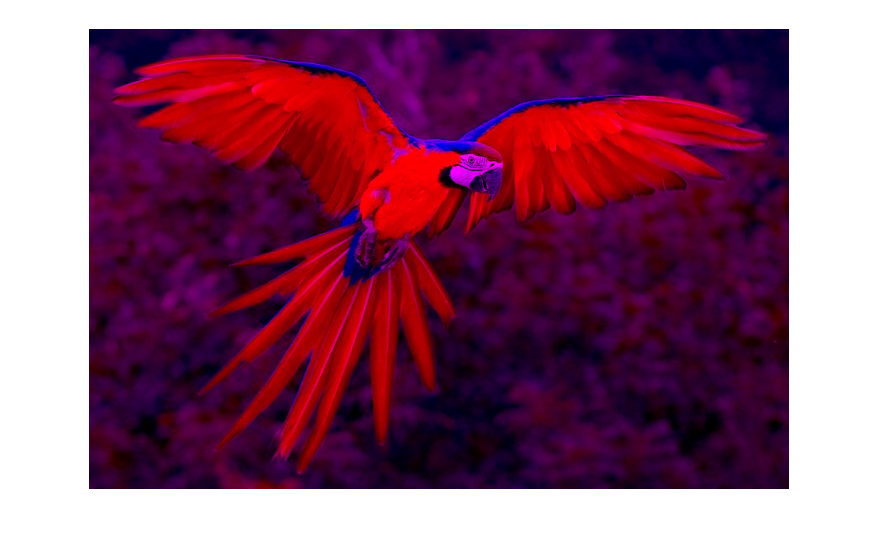

guaca(:,:,2)=0;
imshow(guaca)

Guardamos la imagen

imwrite(B1_binary,'guacamaya_MiguelGutierrez_JulianRamirez.bmp')

#### Rostros

rostro1 = imread('rostro1.jpg');
rostro2 = imread('rostro2.jpg');

Sabemos que los rostros son de 1021x2013, luego:

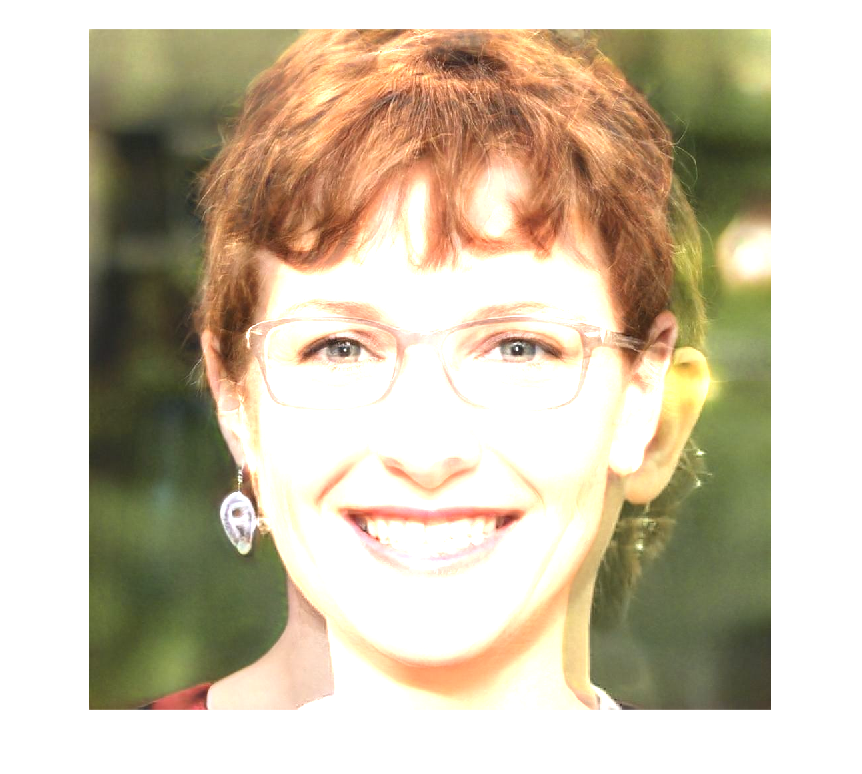

rostros_c = zeros(1021,2013,3);
rostros_c = rostro1 + rostro2;
imshow(rostros_c)